[header]=edfread('Subject00_1.edf','assignToVariables',true)

Step 1 of 2: Reading requested records. (This may take a few minutes.)...
Step 2 of 2: Parsing data...


header = struct with fields:
            ver: 0
      patientID: '0 M 01-JAN-1990 Subject0                                                        '
       recordID: 'Startdate 01-JAN-2011 0 Doctor NeuroCom_Professional_3.0.0                      '
      startdate: '01.01.11'
      starttime: '00.00.00'
          bytes: 5888
        records: 182
       duration: 1
             ns: 22
          label: {'EEGFp1'  'EEGFp2'  'EEGF3'  'EEGF4'  'EEGF7'  'EEGF8'  'EEGT3'  'EEGT4'  'EEGC3'  'EEGC4'  'EEGT5'  'EEGT6'  'EEGP3'  'EEGP4'  'EEGO1'  'EEGO2'  'EEGFz'  'EEGCz'  'EEGPz'  'EEGA2A1'  'ECGECG'  'EDFAnnotations'}
     transducer: {1×22 cell}
          units: {'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'uV'  'mV'  ''}
    physicalMin: [-45.1698 -69.2185 -73.6162 -50.1026 -56.3404 -57.2507 -61.1141 -45.2072 -50.0255 -45.4491 -61.9776 -48.2759 -51.5118 -53.3472 -63.3151 -77.3661 -47.3684 -55.4440 -52.0045 -13.5630 -0.2050 -

% Filter Design
delta = designfilt('bandpassiir','FilterOrder',6, ...
    'HalfPowerFrequency1',0.1,'HalfPowerFrequency2',3.99, ...
    'SampleRate',500);
theta = designfilt('bandpassiir','FilterOrder',6, ...
    'HalfPowerFrequency1',4,'HalfPowerFrequency2',7.99, ...
    'SampleRate',500);
alfa = designfilt('bandpassiir','FilterOrder',6, ...
    'HalfPowerFrequency1',8,'HalfPowerFrequency2',13.99, ...
    'SampleRate',500);
beta = designfilt('bandpassiir','FilterOrder',6, ...
    'HalfPowerFrequency1',14,'HalfPowerFrequency2',30, ...
    'SampleRate',500);
% Graph Variables
L = 91000;
Fs = 500;
t = 0:1/Fs:(L-1)/Fs;
dout = filter(delta,EEGFp1);
tout = filter(theta,EEGFp1);
aout = filter(alfa,EEGFp1);
bout = filter(beta,EEGFp1);

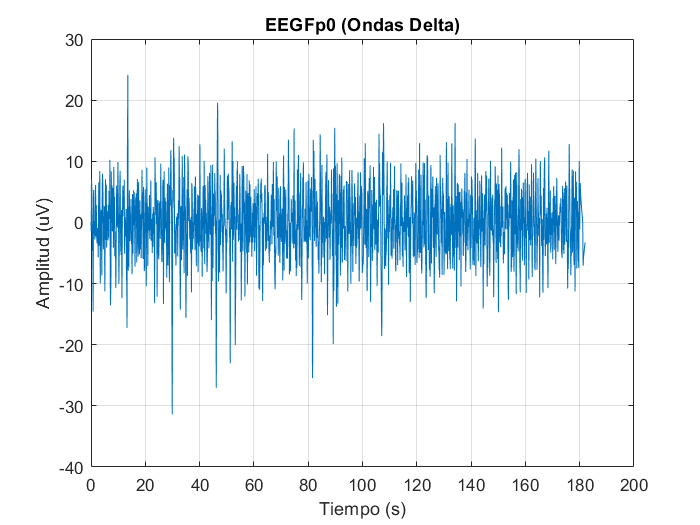

% Plotting Delta
plot(t,dout)
title('EEGFp0 (Ondas Delta)')
grid
ylabel('Amplitud (uV)')
xlabel('Tiempo (s)')

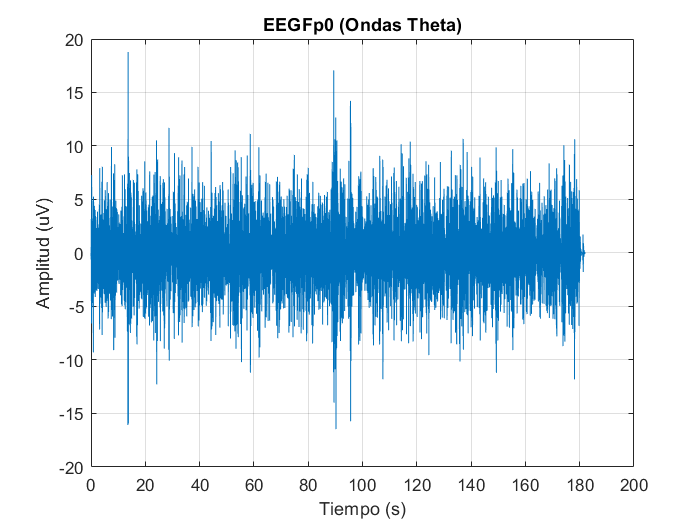

% Plotting Theta
plot(t,tout)
title('EEGFp0 (Ondas Theta)')
grid
ylabel('Amplitud (uV)')
xlabel('Tiempo (s)')

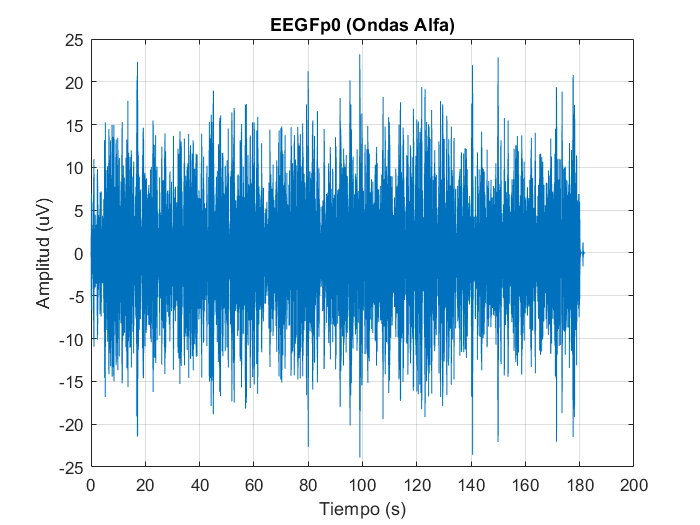

% Plotting Alfa
plot(t,aout)
title('EEGFp0 (Ondas Alfa)')
grid
ylabel('Amplitud (uV)')
xlabel('Tiempo (s)')

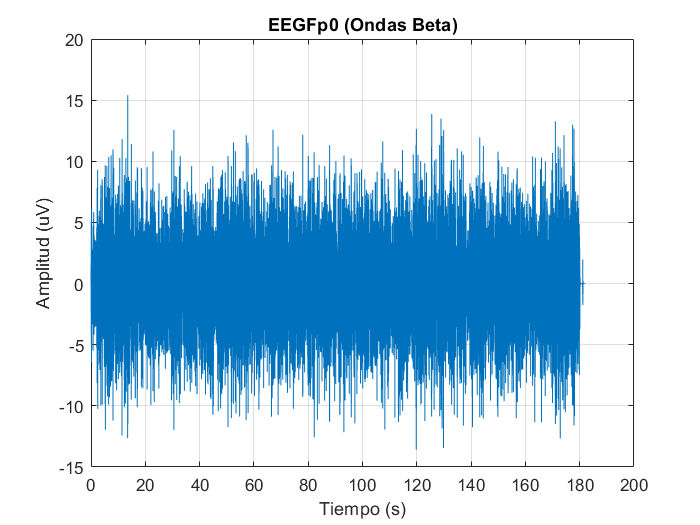

%Plotting Beta
plot(t,bout)
title('EEGFp0 (Ondas Beta)')
grid
ylabel('Amplitud (uV)')
xlabel('Tiempo (s)')

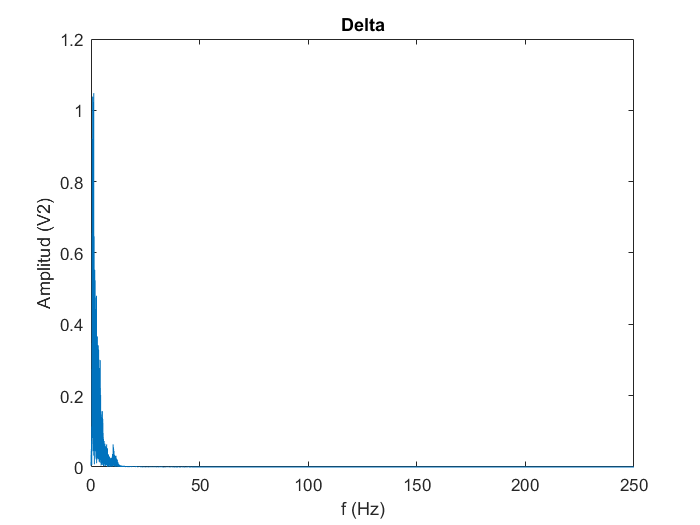

% Fast Fourier Transform
Delta = fft(dout);
f = Fs*(0:(L/2))/L;
P2 = abs(Delta/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(f,P1) 
title('Delta')•
xlabel('f (Hz)')
ylabel('Amplitud (V2)')

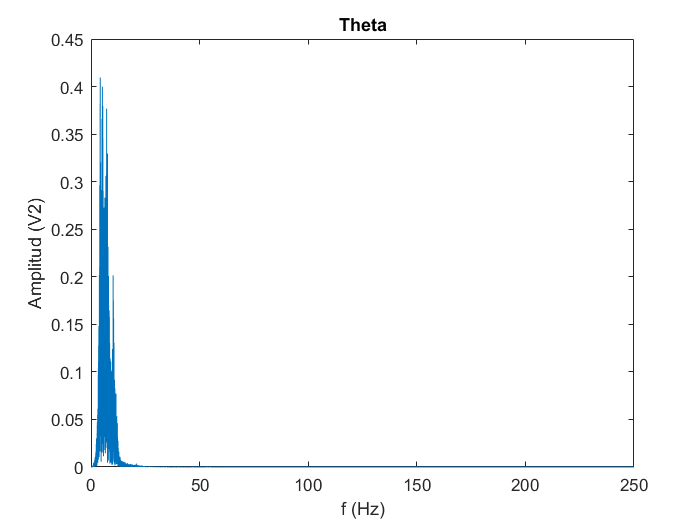

% Fast Fourier Transform
Teta = fft(tout);
f = Fs*(0:(L/2))/L;
P2 = abs(Teta/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(f,P1) 
title('Theta')
xlabel('f (Hz)')
ylabel('Amplitud (V2)')

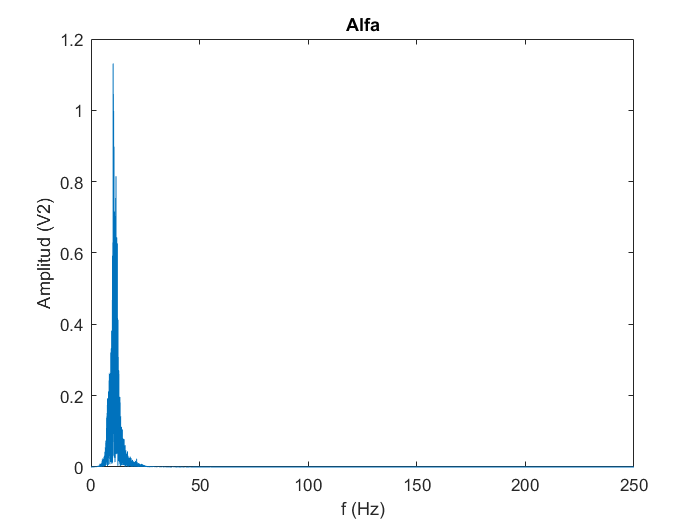

% Fast Fourier Transform
Alpha = fft(aout);
f = Fs*(0:(L/2))/L;
P2 = abs(Alpha/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(f,P1) 
title('Alfa')
xlabel('f (Hz)')
ylabel('Amplitud (V2)')

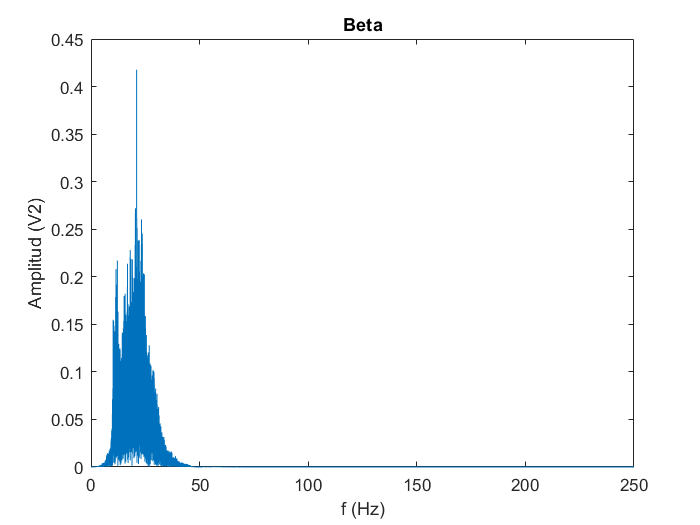

% Fast Fourier Transform
Beta = fft(bout);
f = Fs*(0:(L/2))/L;
P2 = abs(Beta/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(f,P1) 
title('Beta')
xlabel('f (Hz)')
ylabel('Amplitud (V2)')